yalmip('clear');

%% Parameters
N = 33; T = 24;
S_base = 100;     % kVA
Vmin = 0.95; Vmax = 1.05;
Tmax = 10;          % Max Tap position (+/-)
dV = 0.01;           % Tap adjustment (pu)
Tset = -Tmax:Tmax;  % Potential tap settings
Tratio = Tset*dV;    % Tap ratios
CBinj = 0.1;

% Network topology (parent of each node; 0 = slack)
parent = [0 1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 2 19 20 21 3 23 24 6 26 27 28 29 30 31 32 33];  % Node i's parent
r = [0; 0.01; 0.012; 0.011; 0.01; 0.015; 0.015; 0.017; 0.018; 0.013; 0.015; 0.015; 0.017; 0.018; 0.013; 0.015; 0.01; 0.012; 0.011; 0.009; 0.01; 0.012; 0.011; 0.01; 0.015; 0.015; 0.017; 0.018; 0.013; 0.015; 0.015; 0.017; 0.018;]/10;  % Ohm
x = [0; 0.03; 0.025; 0.02; 0.03; 0.035; 0.03; 0.04; 0.045; 0.033; 0.035; 0.03; 0.04; 0.045; 0.033; 0.03; 0.025; 0.02; 0.03; 0.022; 0.03; 0.025; 0.02; 0.03; 0.035; 0.03; 0.04; 0.045; 0.033; 0.035; 0.03; 0.04; 0.045;]/10;     % Ohm

%% Load Data
base_loads = [0; 50; 120; 110; 0; 45; 30; 0; 25; 20; 0; 15; 20; 30; 0; 25; 0; 0; 20; 15; 20; 0; 50; 0; 0; 120; 0; 110; 0; 0; 45; 0; 15];  % kW
pf = 0.95; theta = acos(pf); tan_phi = tan(theta);

load_profile = [ ...
    0.3 0.3 0.35 0.4 0.5 0.7 0.9 1.1 ...
    1.2 1.25 1.2 1.15 1.1 1.0 0.95 0.9 ...
    0.85 0.75 0.6 0.5 0.45 0.4 0.35 0.3];

% Real and reactive power loads (pu)
P_load = zeros(N, T);
Q_load = zeros(N, T);
for t = 1:T
    P_load(:, t) = base_loads * load_profile(t) / S_base;
    Q_load(:, t) = P_load(:, t) * tan_phi;
end

%% YALMIP Variables
P = sdpvar(N, T, 'full');   % Real power flow
Q = sdpvar(N, T, 'full');   % Reactive power flow
v = sdpvar(N, T, 'full');   % Squared voltage
I2 = sdpvar(N, T, 'full');  % Squared current
Tpos = sdpvar(T);           % Tap Positions
d = binvar(length(Tset), T, 'full'); % Tap Decision Matrix
Qcb = sdpvar(3, T, 'full'); % CB Reactive Power
c = binvar(3, 10, T, 'full');   % CB Controls
b = binvar(3, 3, T, 'full');

%% Objective: Minimize total line losses
obj = 0;
for t = 1:T
    for i = 2:N
        obj = obj + r(i) * I2(i, t);
    end
end

%% Constraints
constraints = [];
for t = 1:T
    constraints = [constraints, v(1,t) == 1];  % Slack bus voltage
    cbi = 1;
    for i = 2:N
        k = parent(i);

        % Power balance equations
        if(i == 3 || i == 12 || i == 15)
            constraints = [constraints, ...
                P(i,t) == P(k,t) - P_load(i,t) - r(i)*I2(i,t), ...
                Q(i,t) == Q(k,t) + Qcb(cbi, t) - Q_load(i,t) - x(i)*I2(i,t)];
            cbi = cbi+1;
        else
            constraints = [constraints, ...
                P(i,t) == P(k,t) - P_load(i,t) - r(i)*I2(i,t), ...
                Q(i,t) == Q(k,t) - Q_load(i,t) - x(i)*I2(i,t)];
        end
        % Voltage drop (DistFlow)
        if i ~= 2
        constraints = [constraints, ...
            v(i,t) == v(k,t) ...
                     - 2*(r(i)*P(i,t) + x(i)*Q(i,t)) ...
                     + (r(i)^2 + x(i)^2)*I2(i,t)];
        end
        % Current limit approximation (SOCP relaxation)
        constraints = [constraints, ...
            P(i,t)^2 + Q(i,t)^2 <= I2(i,t) * v(k,t)];
    end
    
    % OLTC Constraints
    constraints = [constraints, v(2, t) == (1 + Tset).^2*d(:,t)];
    constraints = [constraints, Tpos(t) == Tset*d(:,t)];
    constraints = [constraints, sum(d(:,t)) == 1];
    % Voltage magnitude limits
    constraints = [constraints, Vmin^2 <= v(:,t) <= Vmax^2];
    
    % CB Constraints
    if (t ~= T)
        for l = 1:3
            for j = 1:3
                constraints = [constraints, ...
                    b(l, j, t) == c(l, j, t) + c(l, j, t+1) - 2*(c(l, j, t)*c(l, j, t+1)), ...
                    (c(l, j, t)*c(l, j, t+1)) <= c(l, j, t), ...
                    (c(l, j, t)*c(l, j, t+1)) <= c(l, j, t+1), ...
                    (c(l, j, t)*c(l, j, t+1)) + 1 >= c(l, j, t) + c(l, j, t+1)];
            end
            constraints = [constraints, Qcb(l, t) == sum(c(l, :, t))*CBinj];
        end
    end
end


%% Solve
ops = sdpsettings('solver','gurobi','verbose',1);
sol = optimize(constraints, obj, ops);

Set parameter Username
Set parameter LicenseID to value 2660695
Set parameter NonConvex to value 2
Academic license - for non-commercial use only - expires 2026-05-05
Gurobi Optimizer version 12.0.1 build v12.0.1rc0 (win64 - Windows 11.0 (26100.2))

CPU model: Intel(R) Core(TM) Ultra 9 185H, instruction set [SSE2|AVX|AVX2]
Thread count: 16 physical cores, 22 logical processors, using up to 22 threads

Non-default parameters:
LogToConsole  0
NonConvex  2

Optimize a model with 4029 rows, 4650 columns and 12279 nonzeros
Model fingerprint: 0x5fa874f8
Model has 1596 quadratic constraints
Variable types: 3240 continuous, 1410 integer (1410 binary)
Coefficient statistics:
  Matrix range     [5e-06, 1e+02]
  QMatrix range    [1e+00, 2e+00]
  QLMatrix range   [1e+00, 1e+00]
  Objective range  [9e-04, 2e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [1e-02, 2e+00]
  QRHS range       [1e+00, 1e+00]
Presolve removed 3936 rows and 4520 columns
Presolve time: 2.87s
Presolved: 221 rows, 2


%% Results
if sol.problem == 0
    disp('Optimization successful');
    v_opt = value(v);
    losses = value(obj);
    currents = value(I2);
    CBs = value(Qcb);
    taps = value(d);
    fprintf('Total losses: %.4f pu\n', losses);
    disp(currents)
    disp(taps)
    disp(v_opt)
    disp(CBs)
else
    disp('Problem with optimization:');
    sol.info
end

Optimization successful


Total losses: 1.8304 pu


       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    1.0236    1.0236    1.3906    1.8215    2.8470    5.5819    9.2255   13.8668   16.5509   17.9937   16.5486   15.1668   13.8668   11.4177   10.2891    9.2255    8.2333    6.4020    4.0967    2.8470    2.2987    1.8215    1.3906    1.0236
    0.4778    0.4778    0.6553    0.8516    1.3318    2.5901    4.3140    6.3903    7.5503    8.1869    7.5488    6.9361    6.3903    5.2920    4.7827    4.3140    3.8380    2.9837    1.8982    1.3318    1.0821    0.8516    0.6553    0.4800
    0.1187    0.1187    0.1642    0.2122    0.3324    0.6412    1.0782    1.5832    1.8565    2.0120    1.8558    1.7056    1.5832    1.3135    1.1887    1.0782    0.9561    0.7417    0.4684    0.3324    0.2711    0.2122    0.1642    0.1198
    0.1187    0.1187    0.1642    0.

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0    

    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    0.9973    0.9973    0.9968    0.9963    0.9954    0.9937    0.9918    0.9901    0.9894    0.9890    0.9894    0.9898    0.9901    0.9910    0.9914    0.9918    0.9923    0.9932    0.9946    0.9954    0.9958    0.9963    0.9968    0.9973
    0.9961    0.9961    0.9953    0.9947    0.9934    0.9909    0.9881    0.9858    0.9848    0.9842    0.9848    0.9854    0.9858    0.9870    0.9876    0.9881    0.9889    0.9902    0.9922    0.9934    0.9940    0.9947    0.9953    0.9960
    0.9947    0.9947    0.9936    0.

    0.3000    0.3000    0.4000    0.4000    0.5000    0.7000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.9000    0.8000    0.6000    0.5000    0.5000    0.4000    0.4000    0.3226
         0         0         0         0         0    0.1000    0.1000    0.1000    0.2000    0.2000    0.2000    0.2000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000         0         0         0         0    0.0274
    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.0448



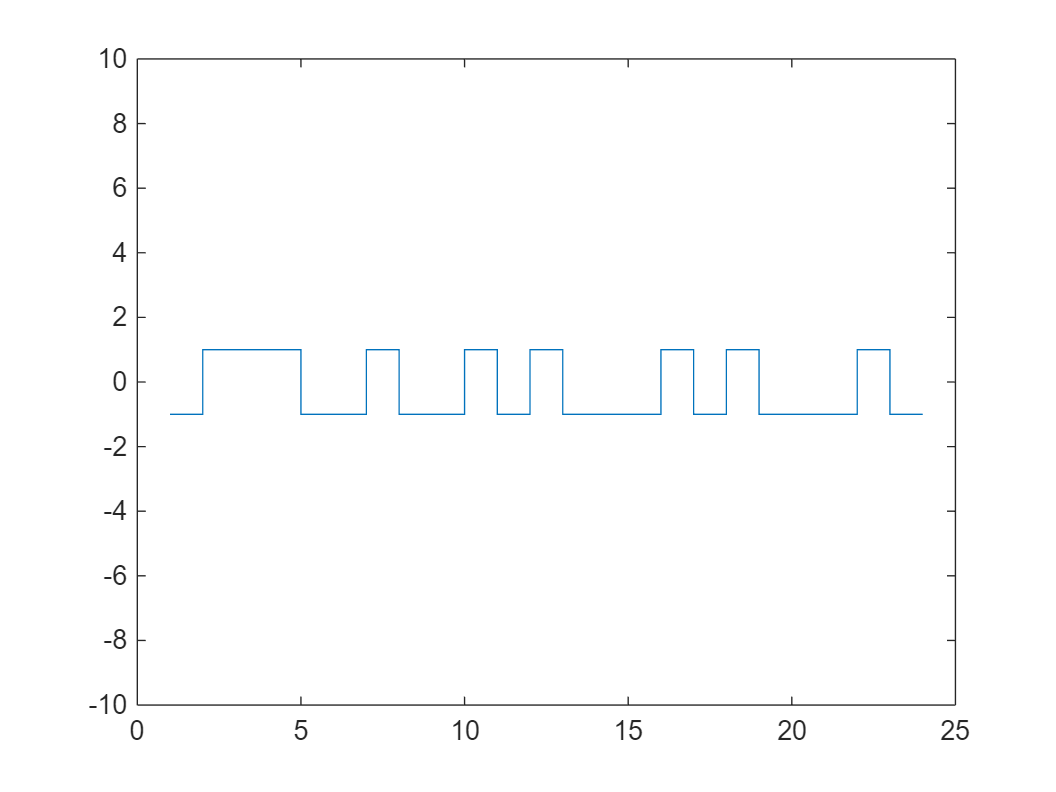


OLTC_ctrl = [];
for i = 1:T
    OLTC_ctrl(i) = find(taps(:,i))-Tmax;
end

stairs(OLTC_ctrl)


stairs(CBs(1,1:T-1))
hold on
stairs(CBs(2,1:T-1))
stairs(CBs(3,1:T-1))
legend("CB1", "CB2", "CB3")
ylim([0, 1]);
hold off